# LAB 6

 5) 

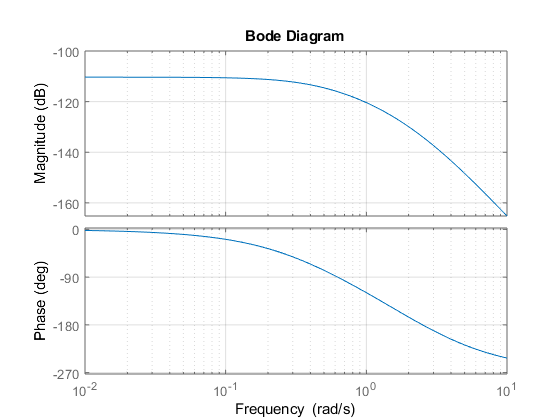

w=logspace(-2,1,100);
[mag, phase, omega] = bode(A,B,C(4,:),D(4,:),1,w);
bode(A,B,C(4,:),D(4,:),1,w)% height tank 2
grid on; 

Qo_Pp =1/100

Qo_Pp =    0.010000000000000


indx = find(mag <= mag(1)*1/100); 
% Find frequencyfor 1% specification 
w0 = omega(indx(1))

w0 =    5.722367659350220


0.01*mag(1)*rho*g

ans =      2.979475251804369e-04


7) 

w=logspace(-2,1,100);
[magh1, phaseh1, omegah1] = bode(A,B,C(1,:),D(1,:),1,w);
[magh2, phaseh2, omegah2] = bode(A,B,C(2,:),D(2,:),1,w);
[magh3, phaseh3, omegah3] = bode(A,B,C(3,:),D(3,:),1,w);

% Compute the new heights
% We take the DC attenuation and add the attenuation next to the specficed 1%
% oscillation 
h1= (magh1(1) + magh1(indx(1)-1))*9800  

h1 =    1.088009849167389


h2= (magh2(1) + magh2(indx(1)-1))*9800 

h2 =    0.951529080820058



h1= (magh3(1) + magh3(indx(1)-1))*9800 

h1 =    0.782359926245471
